clc, clear all
%%plot stuff
beta = 0.1;
Npts = 10;
t_max = 3.2 / beta;
T = linspace(0, t_max, t_max*Npts);
U = T .* beta;
R = 4.*[0.3960*cos(2.65*(U+1.4)) ; -0.99*sin(U+1.4)];
clf
hold on
plot(R(1,:), R(2,:),'-')
plot(R(1,:), R(2,:),'.', "Markersize", 10)
%%symbolic matlab to find other stuff


%%u = beat * t
syms t u

ri=4*0.3960*cos(2.65*(t * beta+1.4));
rj=4*-0.99*sin(t * beta+1.4);
rk=0*t;
r=[ri,rj,rk];


v = diff(r, t);

T_hat = (v ./ norm(v));
dT_hat = diff(T_hat, t);
N_hat = (dT_hat ./ norm(dT_hat))

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sigma_{3}}{\sigma_{1}} & \frac{\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left|\sigma_{2}\right|}^{2}+{\left|\sigma_{3}\right|}^{2}}\\ \sigma_{2}=\frac{99\,\sin\left(\frac{t}{10}+\frac{7}{5}\right)}{2500\,\sqrt{\sigma_{5}}}-\frac{99\,\cos\left(\frac{t}{10}+\frac{7}{5}\right)\,\sigma_{4}}{500\,{\sigma_{5}}^{3/2}}\\ \sigma_{3}=\frac{278091\,\cos\left(\frac{53\,t}{200}+\frac{371}{100}\right)}{2500000\,\sqrt{\sigma_{5}}}+\frac{5247\,\sigma_{6}\,\sigma_{4}}{25000\,{\sigma_{5}}^{3/2}}\\ \sigma_{4}=\frac{9801\,\mathrm{sign}\left(\cos\left(\frac{t}{10}+\frac{7}{5}\right)\right)\,\sin\left(\frac{t}{10}+\frac{7}{5}\right)\,\left|\cos\left(\frac{t}{10}+\frac{7}{5}\right)\right|}{312500}-\frac{1459143477\,\left|\sigma_{6}\right|\,\mathrm{sign}\left(\sigma_{6}\right)\,\cos\left(\frac{53\,t}{200}+\frac{371}{100}\right)}{15625000000}\\ \sigma_{5}=\frac{27531009\,{\left|\sigma_{6}\right|}^{2}}{156250000}+\frac{9801\,{\left|\cos\left(\frac{t}{10}+\frac{7}{5}\right)\right|}^{2}}{62500}\\ \sigma_{6}=\sin\left(\frac{53\,t}{200}+\frac{371}{100}\right) \end{array}$$



%%
for i = 1:5:32
    t = i
    T_hat_eval = eval(subs(T_hat));
    N_hat_eval = eval(subs(N_hat));
    plot([R(1,t*Npts);R(1,t*Npts)+T_hat_eval(1)], [R(2,t*Npts);R(2,t*Npts)+T_hat_eval(2)], "k", "Linewidth", 2)
    plot([R(1,t*Npts);R(1,t*Npts)+N_hat_eval(1)], [R(2,t*Npts);R(2,t*Npts)+N_hat_eval(2)], "b", "Linewidth", 2)
end

t = 1

t = 6

t = 11

t = 16

t = 21

t = 26

t = 31

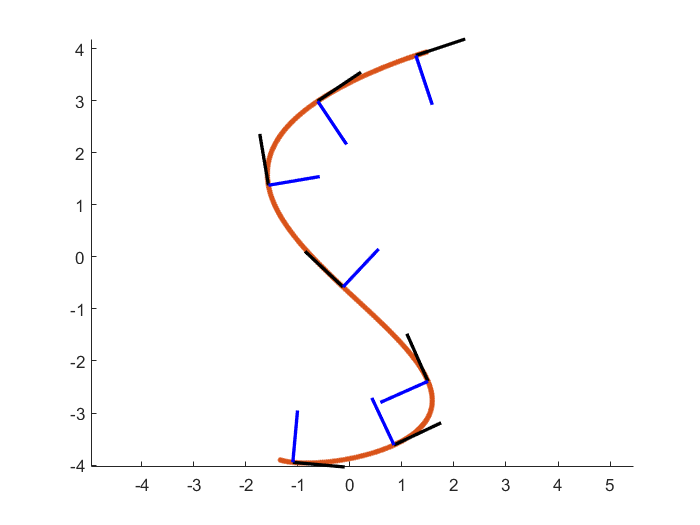

axis equal


dT_hat = diff(T_hat, t);

Check for incorrect argument data type or missing argument in call to function 'isSymType'.
Error in sym/diff (line 68)
      isGoodDiffVar = isSymType(aChild, "symfun");

N_hat = (dT_hat ./ norm(dT_hat))


